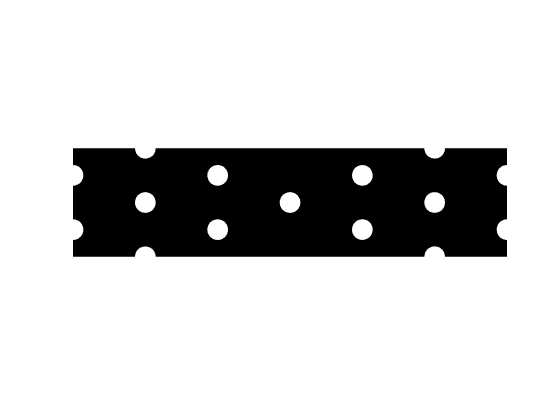

nelx=90;nely=25;volfrac=0.4;
%% LEVEL SET FUNCTION INITIALIZATION
r = nely*0.1;%RADIUS OF INITIAL HOLES
hX = nelx*[repmat([1/6,5/6],1,3),repmat([0,1/3,2/3,1],1,2),1/2];
hY = nely*[kron([0,1/2,1],ones(1,2)),kron([1/4,3/4],ones(1,4)),1/2];
[X,Y] = meshgrid(0:1:nelx,0:1:nely);
dX = bsxfun(@minus,repmat(X,[1,1,numel(hX)]),reshape(hX,1,1,numel(hX)));
dY = bsxfun(@minus,repmat(Y,[1,1,numel(hY)]),reshape(hY,1,1,numel(hY)));
Phi = max(-3,min(3,min(sqrt(dX.^2+dY.^2)-r,[],3)));
pGpX = ([Phi(:,2:end) zeros(nely+1,1)] - [zeros(nely+1,1) Phi(:,1:end-1)]);
pGpY = ([Phi(2:end,:);zeros(1,nelx+1)] - [zeros(1,nelx+1); Phi(1:end-1,:)]);
gradPhi = sqrt((pGpX).^2+(pGpY).^2);
figure(1); contourf(Phi,[0,0]);
colormap([0,0,0]); set(gcf,'color','w'); axis equal; axis off;

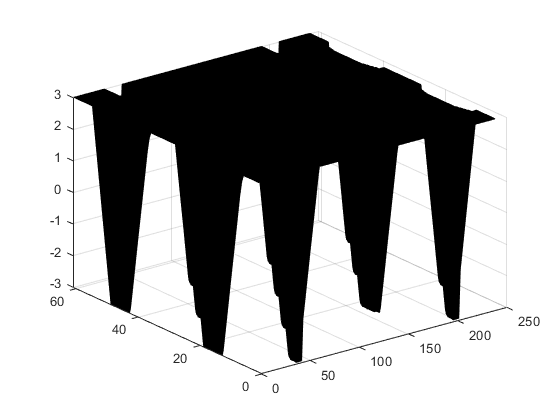

figure(2); surf(Phi); caxis([-12,12]);

No.1, Obj:315468.352203, Vol:0.912566


No.2, Obj:303907.757925, Vol:0.917132


No.3, Obj:294843.262657, Vol:0.918897


No.4, Obj:289709.687973, Vol:0.915649


No.5, Obj:286926.209549, Vol:0.906617


No.6, Obj:383636.498616, Vol:0.776642


No.7, Obj:278636.735375, Vol:0.923434


No.8, Obj:362520.193419, Vol:0.742767


No.9, Obj:271893.544967, Vol:0.944029


No.10, Obj:356799.259064, Vol:0.699210


No.11, Obj:266402.389733, Vol:0.964162


No.12, Obj:366467.923271, Vol:0.647297


No.13, Obj:259642.982272, Vol:0.998035


No.14, Obj:398786.293090, Vol:0.581275


No.15, Obj:259642.982272, Vol:0.998035


No.16, Obj:350800.851768, Vol:0.656401


No.17, Obj:260013.960828, Vol:0.962240


No.18, Obj:586021.935625, Vol:0.542445


No.19, Obj:259642.982272, Vol:0.998035


No.20, Obj:457582.933597, Vol:0.558175


No.21, Obj:259642.982272, Vol:0.998035


No.22, Obj:1493742.250506, Vol:0.384729


No.23, Obj:259642.982272, Vol:0.998035


No.24, Obj:555985.825541, Vol:0.531441


No.25, Obj:259642.982272, Vol:0.998035


No.26, Obj:5150093.377583, Vol:0.349244


No.27, Obj:259642.982272, Vol:0.998035


No.28, Obj:2484206.910248, Vol:0.439829


No.29, Obj:259642.982272, Vol:0.998035


No.30, Obj:1610654.460221, Vol:0.492948


No.31, Obj:259642.982272, Vol:0.998035


No.32, Obj:259642.982272, Vol:0.998035


No.33, Obj:259642.982272, Vol:0.998035


No.34, Obj:259642.982272, Vol:0.998035


No.35, Obj:259695.191180, Vol:0.977955


No.36, Obj:260051.805825, Vol:0.962549


No.37, Obj:261110.254368, Vol:0.946383


No.38, Obj:261728.390314, Vol:0.932179


No.39, Obj:267839.871244, Vol:0.898569


No.40, Obj:394641.693021, Vol:0.765933


No.41, Obj:377687.352737, Vol:0.689079


No.42, Obj:371876.175352, Vol:0.655888


No.43, Obj:582159.279210, Vol:0.583973


No.44, Obj:457625.905659, Vol:0.566095


No.45, Obj:432123.119603, Vol:0.552965


No.46, Obj:423536.415984, Vol:0.532526


No.47, Obj:422012.122663, Vol:0.514026


No.48, Obj:422569.609353, Vol:0.500746


No.49, Obj:423337.894035, Vol:0.493716


No.50, Obj:424702.115821, Vol:0.488610


No.51, Obj:424897.003210, Vol:0.484951


No.52, Obj:425764.518739, Vol:0.481566


No.53, Obj:426071.121100, Vol:0.479688


No.54, Obj:425369.716176, Vol:0.480557


No.55, Obj:422731.340148, Vol:0.482470


No.56, Obj:421157.158418, Vol:0.483863


No.57, Obj:420302.972858, Vol:0.484092


No.58, Obj:419171.770398, Vol:0.484905


No.59, Obj:418042.766618, Vol:0.485905


No.60, Obj:416965.253911, Vol:0.486926


No.61, Obj:415932.623142, Vol:0.487914


No.62, Obj:414892.014475, Vol:0.488945


No.63, Obj:413755.278163, Vol:0.490131


No.64, Obj:412451.754048, Vol:0.491661


No.65, Obj:411357.380138, Vol:0.492853


No.66, Obj:410489.788565, Vol:0.493723


No.67, Obj:409692.371044, Vol:0.494526


No.68, Obj:409077.615878, Vol:0.494997


No.69, Obj:408346.375761, Vol:0.495735


No.70, Obj:407681.162266, Vol:0.496407


No.71, Obj:406996.601469, Vol:0.497135


No.72, Obj:406356.336495, Vol:0.497758


No.73, Obj:405624.497387, Vol:0.498548


No.74, Obj:405154.419763, Vol:0.498890


No.75, Obj:404707.068245, Vol:0.499243


No.76, Obj:404262.284887, Vol:0.499611


No.77, Obj:403900.942756, Vol:0.499846


No.78, Obj:403604.683427, Vol:0.499954


No.79, Obj:403327.534607, Vol:0.500086


No.80, Obj:403347.862391, Vol:0.499778


No.81, Obj:403714.380570, Vol:0.499297


No.82, Obj:403475.174164, Vol:0.499579


No.83, Obj:402796.395438, Vol:0.500264


No.84, Obj:402499.489745, Vol:0.500345


No.85, Obj:402125.719537, Vol:0.500503


No.86, Obj:401821.573622, Vol:0.500629


No.87, Obj:401795.088026, Vol:0.500355


No.88, Obj:401690.755619, Vol:0.500183


No.89, Obj:401486.524006, Vol:0.500222


No.90, Obj:401217.986877, Vol:0.500389


No.91, Obj:401011.518359, Vol:0.500420


No.92, Obj:400805.929308, Vol:0.500415


No.93, Obj:400642.678476, Vol:0.500323


No.94, Obj:400423.023276, Vol:0.500378


No.95, Obj:400315.188822, Vol:0.500236


No.96, Obj:400317.371277, Vol:0.499909


No.97, Obj:400251.582694, Vol:0.499740


No.98, Obj:400101.456978, Vol:0.499726


No.99, Obj:400070.519200, Vol:0.499493


No.100, Obj:399858.069602, Vol:0.499603


No.101, Obj:399755.104950, Vol:0.499509


No.102, Obj:399586.896205, Vol:0.499544


No.103, Obj:399362.073563, Vol:0.499661


No.104, Obj:399154.037333, Vol:0.499766


No.105, Obj:398964.719307, Vol:0.499837


No.106, Obj:398816.358411, Vol:0.499832


No.107, Obj:398582.131035, Vol:0.499992


No.108, Obj:398348.942719, Vol:0.500148


No.109, Obj:398127.963160, Vol:0.500280


No.110, Obj:397958.348448, Vol:0.500314


No.111, Obj:397817.762413, Vol:0.500310


No.112, Obj:397715.057661, Vol:0.500226


No.113, Obj:397697.941889, Vol:0.499982


No.114, Obj:397510.066922, Vol:0.500050


No.115, Obj:397384.728229, Vol:0.499978


No.116, Obj:397305.592318, Vol:0.499846


No.117, Obj:397148.941503, Vol:0.499844


No.118, Obj:397075.321120, Vol:0.499716


No.119, Obj:396907.457538, Vol:0.499748


No.120, Obj:396848.428324, Vol:0.499565


No.121, Obj:396916.994411, Vol:0.499151


No.122, Obj:396896.446488, Vol:0.498937


No.123, Obj:396786.923668, Vol:0.498902


No.124, Obj:396575.930234, Vol:0.499051


No.125, Obj:396309.206855, Vol:0.499310


No.126, Obj:396012.889570, Vol:0.499632


No.127, Obj:395668.723830, Vol:0.500052


No.128, Obj:395390.658045, Vol:0.500352


No.129, Obj:395221.428221, Vol:0.500447


No.130, Obj:395032.733040, Vol:0.500572


No.131, Obj:394955.330275, Vol:0.500511


No.132, Obj:394788.674910, Vol:0.500625


No.133, Obj:394734.820424, Vol:0.500530


No.134, Obj:394721.393881, Vol:0.500358


No.135, Obj:394691.708574, Vol:0.500235


No.136, Obj:394723.176387, Vol:0.500002


No.137, Obj:394659.461881, Vol:0.499947


No.138, Obj:394553.174462, Vol:0.499974


No.139, Obj:394481.031344, Vol:0.499938


No.140, Obj:394439.038015, Vol:0.499845


No.141, Obj:394419.022011, Vol:0.499717


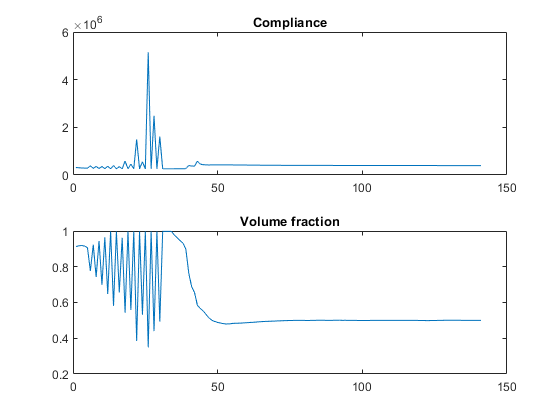

%% RADIAL BASIS FUNCTION INITIALIZATION
nNode = (nely+1)*(nelx+1);
Boundary = setdiff(unique([1:1:nely+1, nNode-nely:1:nNode, nely+1:nely+1:nNode, 1:nely+1:nNode-nely]),[(nely+1)*(ceil(nelx/2)+1),0.1*nelx*(nely+1)+1,0.9*nelx*(nely+1)+1]);
Phi(Boundary)=-1e-9;
Alpha = Phi(:);
Phi = reshape(Alpha,nely+1,nelx+1);
%% FINITE ELEMENT ANALYSIS PREPARATION
E0 = 1; Emin = 1e-9; nu = 0.3; %MATERIAL PROPERTIES
A11 = [12 3 -6 -3; 3 12 3 0; -6 3 12 -3; -3 0 -3 12];
A12 = [-6 -3 0 3; -3 -6 -3 -6; 0 -3 -6 3; 3 -6 3 -6];
B11 = [-4 3 -2 9; 3 -4 -9 4; -2 -9 -4 -3; 9 4 -3 -4];
B12 = [ 2 -3 4 -9; -3 2 9 -2; 4 9 2 3; -9 -2 3 2];
KE = 1/(1-nu^2)/24*([A11 A12;A12' A11]+nu*[B11 B12;B12' B11]);
eleN1 = repmat((1:nely)',1,nelx)+kron(0:nelx-1,(nely+1)*ones(nely,1));
eleNode = repmat(eleN1(:),1,4)+repmat([0,nely+[1,2],1],nelx*nely,1);
edofMat = kron(eleNode,[2,2])+repmat([-1,0],nelx*nely,4);
iK = reshape(kron(edofMat,ones(8,1))',64*nelx*nely,1);
jK = reshape(kron(edofMat,ones(1,8))',64*nelx*nely,1);
%% BOUNDARY CONDITION DEFINITION
F = sparse(2*((nely+1)*(ceil(nelx/2)+1)),1,-100,2*nNode,1);
fixeddofs = [2*0.1*nelx*(nely+1)+2,2*0.9*nelx*(nely+1)+2];
freedofs = setdiff(1:2*nNode,fixeddofs);
U = zeros(2*nNode,1);
%% ITERATION OPTIMIZATION
nLoop = 500; nRelax = 30;
dt = 0.2; delta = 20; mu = 20; gamma = 0.05;
comp = zeros(nLoop,1); vol = zeros(nLoop,1);
for iT = 1:nLoop
    %% FINITE ELEMENT ANALYSIS
        [s,t] = meshgrid(-1:0.1:1,-1:0.1:1);
    tmpPhi = (1-s(:)).*(1-t(:))/4*Phi(eleNode(:,1))'+(1+s(:)).*(1-t(:))/4*...
        Phi(eleNode(:,2))'+(1+s(:)).*(1+t(:))/4*Phi(eleNode(:,3))'+...
        (1-s(:)).*(1+t(:))/4*Phi(eleNode(:,4))';
    eleVol = sum(tmpPhi>=0,1)'/numel(s);
    vol(iT) = sum(eleVol)/(nelx*nely);
    sK = reshape(KE(:)*(Emin+eleVol'*(E0-Emin)),64*nelx*nely,1);
    K = sparse(iK,jK,sK); K = (K+K')/2;
    U(freedofs,1) = K(freedofs,freedofs)\F(freedofs,1);
    eleComp = sum((U(edofMat)*KE).*U(edofMat),2).*(Emin+eleVol*(E0-Emin));
    comp(iT) = sum(eleComp);
    %% DISPLAY RESULTS
    fprintf('No.%i, Obj:%f, Vol:%f\n',[iT,comp(iT),vol(iT)]);
    figure(3); contourf(Phi,[0,0]);
    colormap([0,0,0]); set(gcf,'color','w'); axis equal; axis off;
    saveas(gcf,sprintf('Optim_pictures/%i.png', iT));
    figure(4); surf(Phi); caxis([-12,12]);
    axis equal; axis([0,nelx,0,nely,-12,12]); view(3);
    figure(5);  subplot(2,1,1); plot(comp(1:iT),'-'); title('Compliance');
                subplot(2,1,2); plot(vol(1:iT),'-'); title('Volume fraction');
    %% CONVERGENCE CHECK
    if iT>nRelax && abs(vol(iT)-volfrac)/volfrac<1e-3 && ...
        all(abs(comp(iT)-comp(iT-9:iT-1))/comp(iT)<1e-3)
        break;
    end
    %% LAGRANGE MULTIPLIER
    if iT<=nRelax
        lag = mu*(vol(iT)-vol(1)+(vol(1)-volfrac)*iT/nRelax);
    else
        lag = lag+gamma*(vol(iT)-volfrac);
        gamma = min(gamma+0.05,5);
    end
    %% LEVEL SET FUNCTION EVOLUTION
    pGpX = ([Phi(:,2:end) zeros(nely+1,1)] - [zeros(nely+1,1) Phi(:,1:end-1)]);
    pGpY = ([Phi(2:end,:);zeros(1,nelx+1)] - [zeros(1,nelx+1); Phi(1:end-1,:)]);
    gradPhi = sqrt((pGpX).^2+(pGpY).^2);
    indexDelta = (abs(Phi(:))<=delta);
    DeltaPhi = zeros(size(Phi));
    DeltaPhi(indexDelta) = 0.75/delta*(1-Phi(indexDelta).^2/delta^2);
    eleComp = reshape(eleComp,nely,nelx);
    eleCompLR = [eleComp(:,1),eleComp]+[eleComp,eleComp(:,end)];
    nodeComp = ([eleCompLR;eleCompLR(end,:)]+[eleCompLR(1,:);eleCompLR])/4;
    B = (nodeComp(:)/median(nodeComp(:))-lag).*DeltaPhi(:)*delta/0.75;
    Alpha = Alpha+dt*B;
    Alpha = Alpha/mean(gradPhi(unique(eleNode((eleVol<1 & eleVol>0),:))));%broke the program when the body is solid, but prevent oscilations
    Phi = reshape(Alpha,nely+1,nelx+1);
    Phi(Boundary)=min(Phi(Boundary),-1e-9);
end